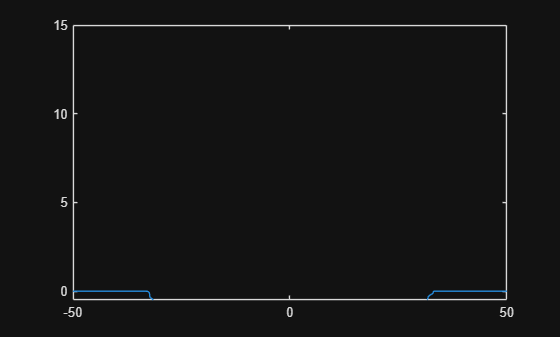

%{play around with z function, timespan, etc. --> try very rough oscillation%}
for k = 1:50

    tau = 1*k;

    alpha = 1;

    omega = 0.1;

    tcross = 1; %{come up withimplicit definition, time where backwards light cone intersects particle world line; integral is 
    %{0 to tcross, think of it like 0 to t --> if particle is not in backwards light cone, = 0, otherwise do the other thing if the
    %{particle is  in the backwards light cone; check notes for this%}

    %{%}

    z = @(t) 0.5 * sin(5*t) .* exp(-t);

    %{besselsource = @(tt,s,z) alpha .* besselj(0, omega .* sqrt(tt.^2 - (s - z).^2));%}
    %{bessel(t, tt, s, z(tt))%}

    Usource = @(t, s) compute_Usource(t, s, z, alpha, omega);%{same as bessel if particle in light cone, %}

    slin = linspace(-50, 50, 2000);

    for i = 1:length(slin)
        solved_Usource(i) = Usource(tau, slin(i));
    end

    plot(slin, solved_Usource)
    axis([-50 50 -0.5 15])
    saveas(gcf, ['Frame' num2str(k) '.png'])

end


function U = compute_Usource(t, s, z, alpha, omega)
    
    if t^2 >= (s - z(t))^2
        U = integral(@(tt) besselCompute(t, tt, s, z(tt), alpha, omega), 0, t);
        %{introduce uInt --> integrand computed at many times between 0 and t
        %{introduce tlin, chop up integral, make uInt a vector where each component is
        %{integrand evaluated at each time of tlin (trapz function)%}
        %{alternate method for B array ^%}
    else
        U = 0;
    end
end

function B = besselCompute(t, tt, s, ztt, alpha, omega)
    n = length(tt);
    B = [];
    for i = 1:n
        if abs(t - tt(i)) > abs(s - ztt(i))
            B(i) = alpha .* besselj(0, omega .* sqrt(t.^2 - (s - ztt(i).^2)));
        else 
            B(i) = 0;
        end
    end
end

